**EE 150**

**Signals and Systems**

** Lab 3 Analysis of Periodic Signals in Frequency Domain**

Date Performed: 2022.10.27

Class Id: Lab3-Thur-105

Name & ID:王鹏豪-2021533138-周守琛-2021533042

1. Use symbolic method to find out the Fourier series of the following square waveform  in trigonometric format . In a 3*1 subplot, draw the superposition of the [2,8,32] harmonic respectively. Each subplot needs the original square wave. At least 3 cycles are required.

Tips: Find out the Fourier series with symbolic method. The original signal can be generated by numeric method.

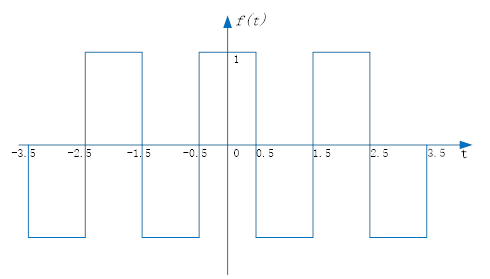

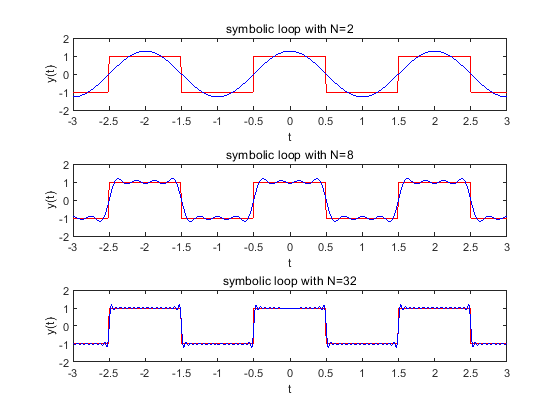

clear;clf;
syms t a0 an bn n
T1 = 2;
freq = 1/T1;
w1 = 2*pi*freq;
range = [-1.5,0.5];
ft = sign(t+0.5);
dt=0.01;
time=-3:dt:3;
for i=1:3
    if i==1
        N=2;
    elseif i==2
        N=8;
    else
        N=32;
    end
    a0 = 1/T1*int(ft,t,range);
    f = a0;
    for n=1:N
        an = 2/T1*int(ft*cos(n*w1*t),t,range);
        bn = 2/T1*int(ft*sin(n*w1*t),t,range);
        f = f+an*cos(n*w1*t)+bn*sin(n*w1*t);
    end
    subplot(3,1,i);
    plot(time,square(pi.*(time+0.5),50),'Color',[1 0 0]); hold on;
    fplot(f,'Color',[0 0 1]); hold off;
    xlabel("t");
    ylabel("y(t)");
    title(["symbolic loop with N=" + num2str(N)]);
    axis([-3,3,-2,2]);
    set(gca,'XTick',[-3:0.5:3]);
    set(gca,'YTick',[-2:1:2]);
end

2. Use matrix operation to find out the spectrum of the following signal in exponantial format. Draw its amplitude-frequency and phase-frequency in  a 2*1 subplot. 

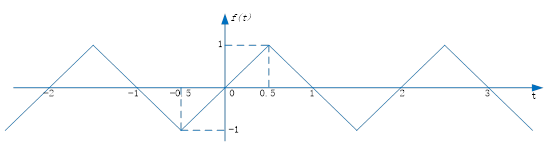

clear;clf;
T = 2;
freq = 1/T;
w1 = 2*pi*freq;
dt = 0.01;
t = -3:dt:3;
tau = -1:dt:1;
ft = sawtooth(pi*tau+pi/2,0.5);
N = 16;

N is chosen to suit the graph better.

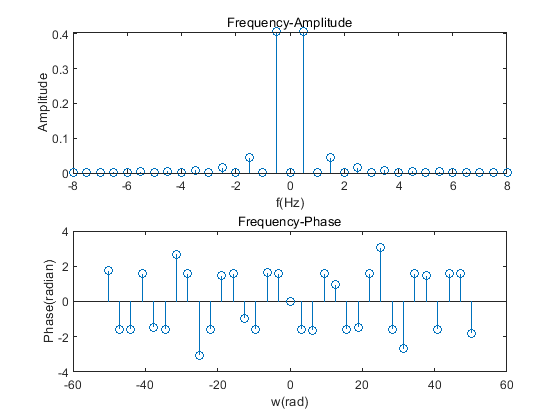

n = -N:N;
Wn = n*w1;
F = ft.*exp(-1j*n'*w1*tau);
Fn = trapz(tau,F,2)/T;

f = Fn.'*exp(1j*n'*w1*t);
subplot(2,1,1);
stem(Wn/(2*pi),abs(Fn));
xlabel("f(Hz)");
ylabel("Amplitude");
title("Frequency-Amplitude");

subplot(2,1,2);
stem(Wn,angle(Fn));
xlabel("w(rad)");
ylabel("Phase(radian)");
title("Frequency-Phase");

3.  Draw the amplitude-frequency of the signal below with the following two sets of parameter in numeric loop method.

(a) $T_1 =1,\tau =\frac{1}{2}$.

(b)  $T_2 =8,\tau =\frac{1}{2}$.

1) Draw (a) and (b) in a 2*1 subplot. Limite the frequency to [-5 5] Hz.

2) Compare the two amplitude-frequency figure, what do you find? Try to summarize.

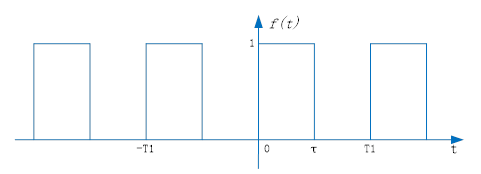

clear;clf;

(1)

Tmerge = [1;8];
freqmerge = 1./Tmerge;
w1merge = 2*pi.*freqmerge;
tau1 = 1/2;
tau2 = 1/2;
dt = 0.01;
t = -3:dt:3;
tau = -1:dt:1;
ft1 = 0.5+0.5*square(pi/tau1*tau,50);
ft2 = 0.5+0.5*square(pi/tau2*tau,50);
ftmerge = [ft1;ft2];
N = 40;

N is chosen to suit the graph better.

since the frequency is limited to [-5 5] Hz, and the period of (b)'s is 8 times of (a),

and (a) sampling at integer of each frequency,

so the N should be 5*8=40.

N balance between quality and performance.

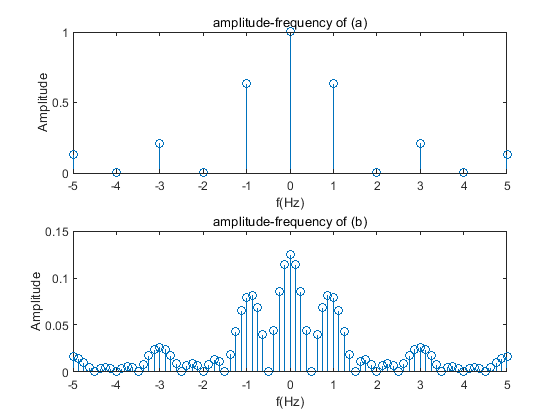

Fn = zeros(1,2*N+1);

for number = 1:2
    i = 1;
    f = 0;
    T = Tmerge(number,:);
    freq = freqmerge(number,:);
    w1 = w1merge(number,:); 
    ft = ftmerge(number,:);
    
    Wn = (-N:N)*w1;
    for n = -N:N
        F = ft.*exp(-1j*n*w1*tau);
        Fn(i) = trapz(tau,F)/T;
        f = f+ Fn(i).*exp(1j*n*w1*t);
        i = i+1;
    end
    subplot(2,1,number);
    stem(Wn/(2*pi),abs(Fn));
    xlabel("f(Hz)");
    ylabel("Amplitude");
    xlim([-5 5]);
    if number==1
        title("amplitude-frequency of (a)");
    else
        title("amplitude-frequency of (b)");
    end
end

(2)

(a) and (b) have the same tao.

But the cycle of (b) has the period 8 times of (a)'s.

The  max Amplitude of (a) is 8 times of (b)'s.

The sampling density of b is 8 times that of a.

4. Music notes are also sine waves with different frequencies. Let's try to play the song here with Matlab. 

Draw every note in both time domain and frequency domain (only amplitude-frequency) synchronously in the 1*2 subplot. The signal in frequency domain should be obtained from the signal in time domain by applying Fourier series analysis.

tips:

a) Set the frequencies and time durations you need as the following lists:  

freq = [50,250,300]    % notes frquency in Hz

duration = [1,2,3]    % notes duration in second 

b) Create a note with function **sin(**$2\pi \textrm{ft}$**)** or **cos(**$2\pi \textrm{ft}$**),** where  t = 0:dt:duration().

c) To play the signal, uses function **sound(yt, Fs)**, where yt is the signal and Fs is the sample frequency (1/dt).

d) When playing a note, wait for it to finish by using function** pause(duration)**.

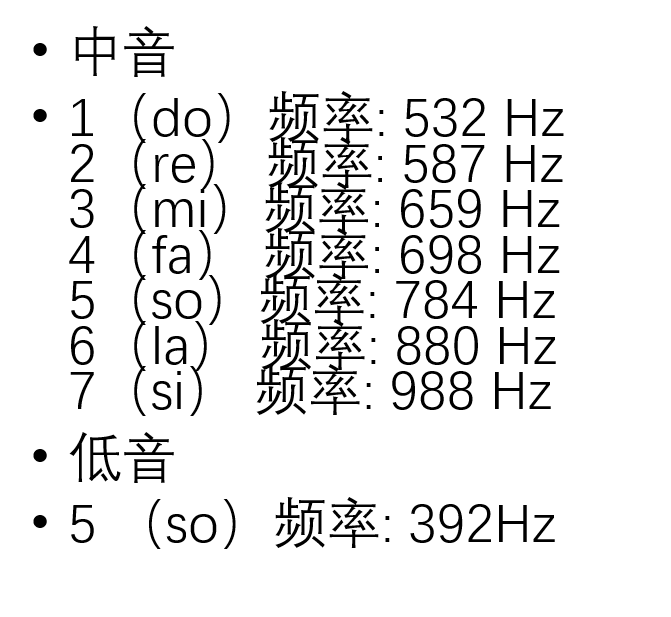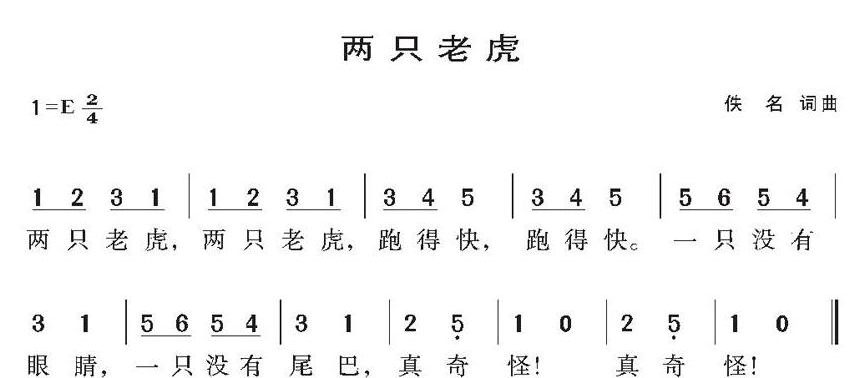

clear;clf;
freq = [532,587,659,698,784,880,988,392];
fs=[1,2,3,1,1,2,3,1,3,4,5,3,4,5,5,6,5,4,3,1,5,6,5,4,3,1,2,8,1,0,2,8,1,0];
duration = [1,1,1,1,1,1,1,1,1,1,2,1,1,2,1,1,1,1,2,2,1,1,1,1,2,2,2,2,2,2,2,2,2,2];


number=34;
dt=0.0005;

the whole note number is 34

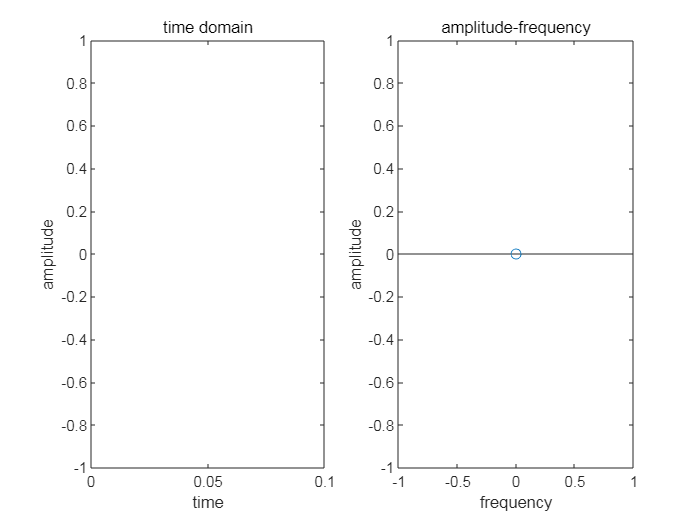

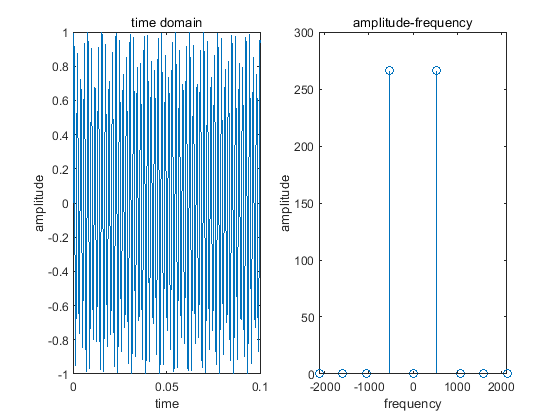

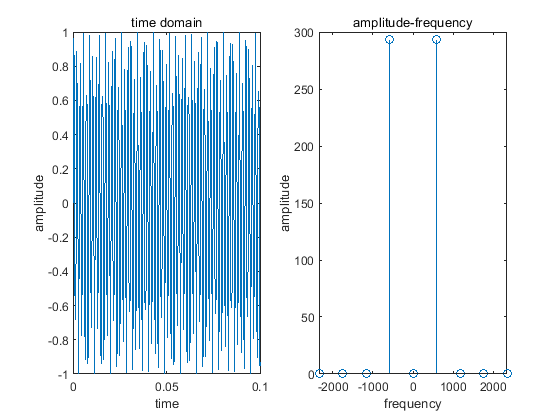

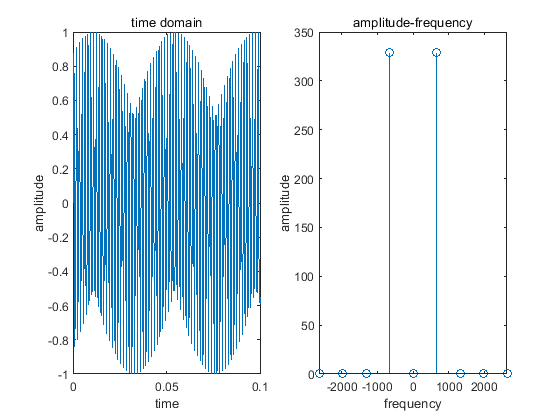

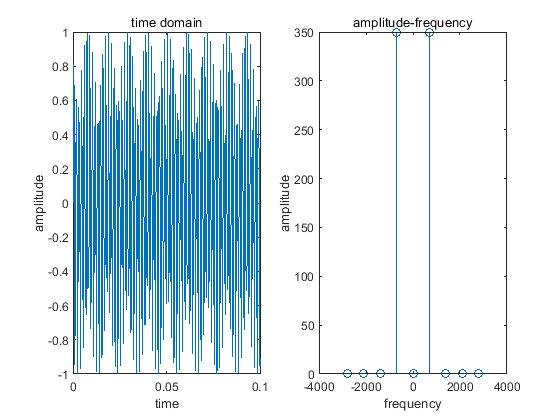

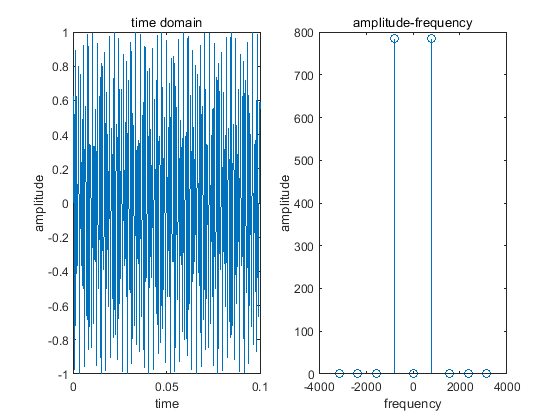

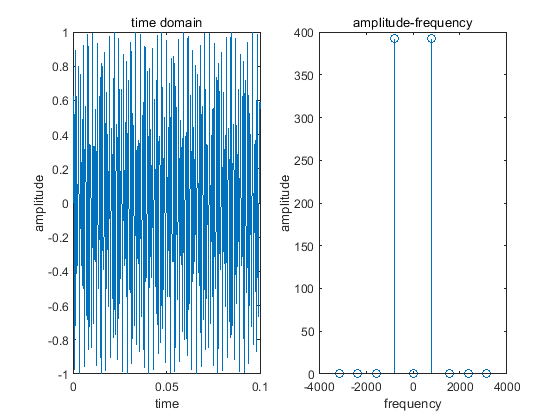

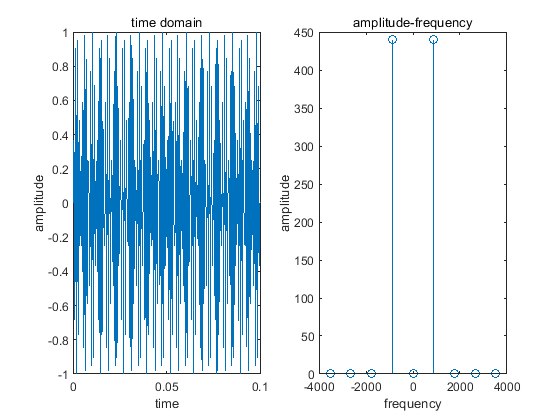

for i = 1:number
    figure(i);
    t = 0:dt:duration(i);
    yt = 0;
    Fs=0;
    if fs(i)~=0
        Fs=freq(fs(i));
        yt=sin(2*pi*Fs*t);
        sound(yt,1/dt);
    end
    pause(duration(i));
    subplot(1,2,1);
    plot(t,yt);
    xlabel("time");
    ylabel("amplitude");
    title("time domain");
    xlim([0 0.1]);
    subplot(1,2,2);
    
    N=4;

    ii = 1;
    f = 0;
    %T = duration(i);
    fre = Fs;
    T=1/fre;
    w1 = 2*pi*fre; 
    tau = t;
    ft = yt;
    
    Wn = (-N:N)*w1;
    for n = -N:N
        F = ft.*exp(-1j*n*w1*tau);
        Fn(ii) = trapz(tau,F)/T;
        f = f+ Fn(ii).*exp(1j*n*w1*t);
        ii = ii+1;
    end
    subplot(1,2,2);
    stem(Wn/(2*pi),abs(Fn));

    xlabel("frequency");
    ylabel("amplitude");
    title("amplitude-frequency");
end